txgrid, rxGrid, H_perfect_n are got from the Gen_Chan_DD,mlx after line 768

txGrid_DD = ifft(fft(txGrid, [], 2), [], 1); % rank(txGrid) =3
rxGrid_DD = ifft(fft(rxGrid, [], 2), [], 1); % rxGrid received by waveform → channel filter

rxGrid_straightTF = txGrid .* H_perfect_n;    % straight compute Y_TF = H_TF . X_TF, not convert to time-domain waveform
                                               % NOTE: the values at the pilot elements are very different with rxGrid
rxGrid_straightTF_toDD = ifft(fft(rxGrid_straightTF, [], 2), [], 1);


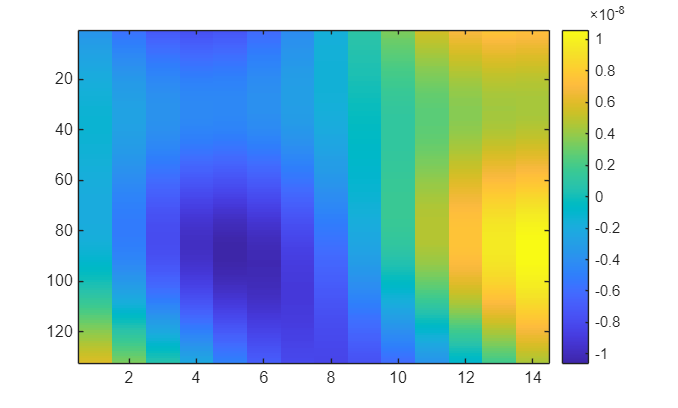

% idx = 60;
% H_li_DD = tf2dd(H_li(:,:,idx).');
% H_prac_DD = tf2dd(H_prac(:,:,idx).');
% H_ls_DD = tf2dd(H_ls(:,:,idx).');
% 
H_perfect_n_DD = ifft(fft(H_perfect_n, [], 2), [], 1);
H_perfect_n_before_DD = ifft(fft(H_perfect_n_before, [], 2), [], 1);

figure; imagesc(real(H_perfect_n)); colorbar

## Not used Compressed Sensing

#### Using channel filter, txWaveform

H_LS_TF = H_equalized_n;
H_LI_TF = zeros(size(H_linear_n));
H_LI_TF(:,3) = H_linear_n(:,3);
H_LI_TF(:,8) = H_linear_n(:,8);
H_LI_TF(:,12) = H_linear_n(:,12);

H_LS_DD = ifft(fft(H_LS_TF, [], 2), [], 1);
H_LI_DD = ifft(fft(H_LI_TF, [], 2), [], 1);

function [H_DD_sparse, H_TF_full, support] = extract_sparse_DD(H_DD, K_sparse)
    % Extract K largest magnitude elements from DD domain channel
    %
    % Inputs:
    %   H_DD - [M x N] channel in DD domain (e.g., H_LS_DD or H_LI_DD)
    %   K_sparse - number of dominant taps to keep
    %
    % Outputs:
    %   H_DD_sparse - [M x N] sparse DD channel (only K non-zeros)
    %   H_TF_full - [M x N] full TF channel (all positions filled)
    %   support - linear indices of the K selected taps
    
    [M, N] = size(H_DD);
    
    %% Step 1: Find K largest magnitude elements
    
    % Flatten to vector
    h_vec = H_DD(:);
    
    % Get magnitudes
    magnitudes = abs(h_vec);
    
    % Sort by magnitude (descending)
    [sorted_mags, sorted_idx] = sort(magnitudes, 'descend');
    
    % Keep top K indices
    support = sorted_idx(1:K_sparse);
    
    fprintf('Extracted %d largest taps:\n', K_sparse);
    fprintf('  Largest:  %.4e\n', sorted_mags(1));
    fprintf('  Smallest: %.4e\n', sorted_mags(K_sparse));
    fprintf('  Ratio:    %.2f\n', sorted_mags(1) / sorted_mags(K_sparse));
    
    %% Step 2: Create sparse DD channel
    
    H_DD_sparse = zeros(M, N);
    h_sparse_vec = zeros(M*N, 1);
    h_sparse_vec(support) = h_vec(support);  % Keep only selected elements
    H_DD_sparse = reshape(h_sparse_vec, [M, N]);
    
    fprintf('  Non-zeros in sparse DD: %d\n', nnz(H_DD_sparse));
    
    %% Step 3: Transform to TF domain (recover full channel)
    
    % DD → TF:  FFT in frequency, IFFT in time
    H_TF_full = fft(ifft(H_DD_sparse, [], 2), [], 1);
    
    fprintf('  Full TF channel: %d x %d (all positions estimated)\n', M, N);
    
end

K_sparse_ = 10;  % Number of dominant taps to keep

%% Process LS estimate
[H_LS_DD_sparse, H_LS_TF_full, support_LS] = extract_sparse_DD(H_LS_DD, K_sparse_);

Extracted 10 largest taps:
  Largest:  7.4701e-09
  Smallest: 5.6014e-09
  Ratio:    1.33
  Non-zeros in sparse DD: 10
  Full TF channel: 132 x 14 (all positions estimated)



%% Process LI estimate
[H_LI_DD_sparse, H_LI_TF_full, support_LI] = extract_sparse_DD(H_LI_DD, K_sparse_);

Extracted 10 largest taps:
  Largest:  2.2339e-08
  Smallest: 6.8605e-09
  Ratio:    3.26
  Non-zeros in sparse DD: 10
  Full TF channel: 132 x 14 (all positions estimated)


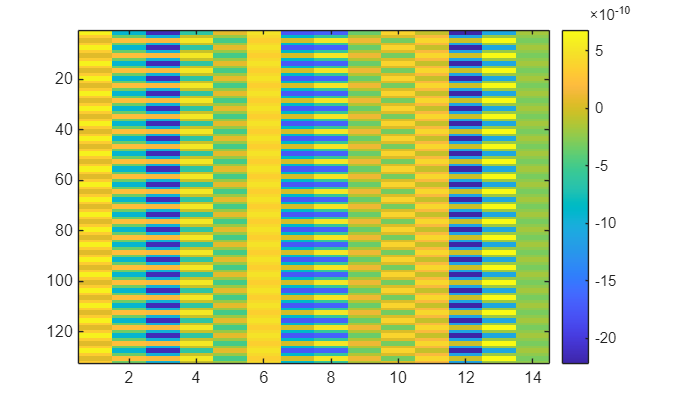

figure
imagesc(real(H_LS_TF_full));
colorbar

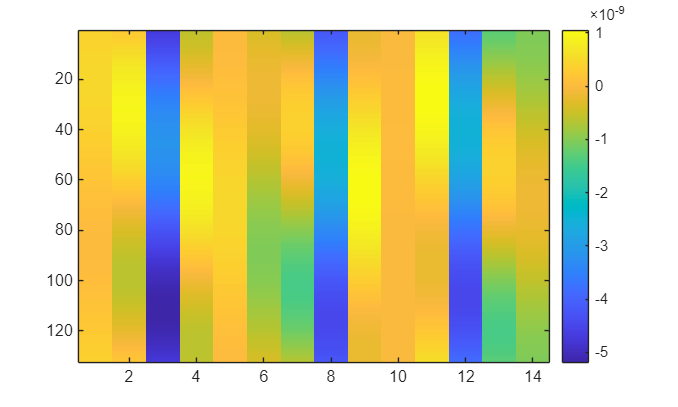


figure
imagesc(real(H_LI_TF_full));
colorbar

→ Not good results

#### Using straight TF grid Y = X .* H

rxGrid_straightTF = txGrid .* H_perfect_n

H_LS_noNoise = H_perfect_n .* (txGrid ~= 0);
H_LS_noNoise_DD = ifft(fft(H_LS_noNoise, [], 2), [], 1);

[~, H_LS_noNoise_TF_full, support_LS] = extract_sparse_DD(H_LS_noNoise_DD, K_sparse_);

Extracted 10 largest taps:
  Largest:  6.8500e-09
  Smallest: 5.1510e-09
  Ratio:    1.33
  Non-zeros in sparse DD: 10
  Full TF channel: 132 x 14 (all positions estimated)


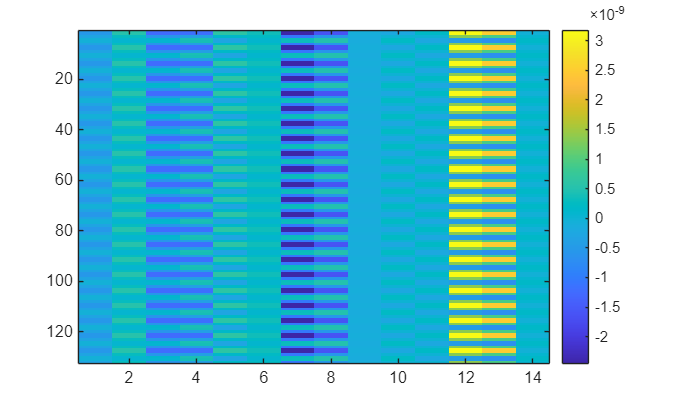

figure
imagesc(real(H_LS_noNoise_TF_full));
colorbar

→ Even with no noise, it is still not good

For LI 

rxGrid_straightTF = txGrid .* H_perfect_n - no Noise considered

function H_LI = linear_interpolate_2D(H_LS_noNoise, pilot_mask)
    % 2D Linear interpolation of channel from pilot positions to all positions
    %
    % Inputs:
    %   H_LS_noNoise - [K x N] channel with values only at pilot positions
    %   pilot_mask - [K x N] logical array (true where pilots exist)
    %
    % Output:
    %   H_LI - [K x N] linearly interpolated channel (all positions)
    
    [K, N] = size(H_LS_noNoise);
    
    % Find row and column coordinates of pilots
    [rows, cols] = find(pilot_mask);
    pilot_values = H_LS_noNoise(pilot_mask);
    
    % Get unique pilot symbols (columns)
    pilot_cols = unique(cols);
    
    %% Check how many pilot symbols we have
    if isscalar(pilot_cols)
        % Only 1 symbol containing pilots -> duplicate
        col_idx = pilot_cols(1);
        
        % Interpolate along rows (subcarriers) for the pilot column
        query_rows = (1:K)';
        H_LI = zeros(K, N);
        H_LI(:, col_idx) = interp1(rows, pilot_values, query_rows, 'linear', 'extrap');
        
        % Duplicate to all other columns
        for n = 1:N
            if n ~= col_idx
                H_LI(:, n) = H_LI(:, col_idx);
            end
        end
        
    else
        % Multiple pilot symbols -> 2D scattered interpolation
        
        % Create query grid (all positions)
        [col_grid, row_grid] = meshgrid(1:N, 1:K);
        
        % Scattered interpolant (column, row, value)
        F = scatteredInterpolant(cols, rows, pilot_values, 'linear', 'nearest');
        
        % Interpolate to all positions
        H_LI = F(col_grid, row_grid);
    end
end

H_LI_noNoise = linear_interpolate_2D(H_LS_noNoise, H_LS_noNoise~=0);
nmse = norm(H_perfect_n - H_LI_noNoise)^2 / norm(H_perfect_n)^2

nmse = 0.1143

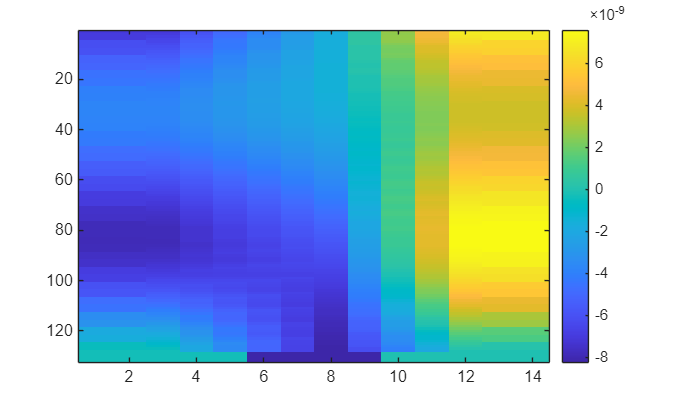

figure
imagesc(real(H_LI_noNoise));
colorbar

→ Even with perfect LS (no noise), LI still not good at the extrapolated elements

H_LI_noNoise_DD = ifft(fft(H_LI_noNoise, [], 2), [], 1);
[~, H_LI_noNoise_TF_full, support_LS] = extract_sparse_DD(H_LI_noNoise_DD, 50); %  K_sparse_

Extracted 50 largest taps:
  Largest:  7.0982e-08
  Smallest: 2.2588e-09
  Ratio:    31.42
  Non-zeros in sparse DD: 50
  Full TF channel: 132 x 14 (all positions estimated)


nmse = norm(H_perfect_n - H_LI_noNoise_TF_full)^2 / norm(H_perfect_n)^2

nmse = 0.1129

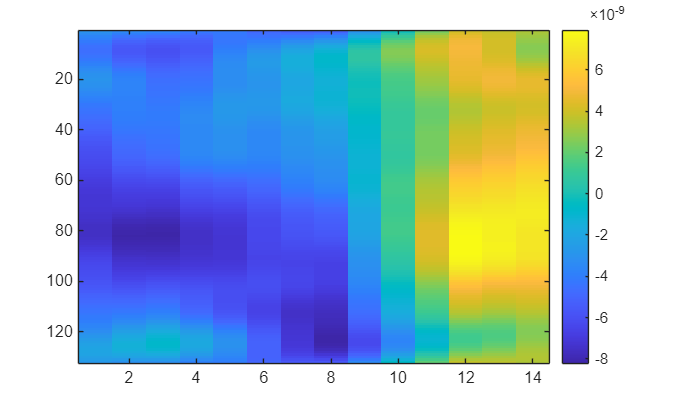

figure
imagesc(real(H_LI_noNoise_TF_full));
colorbar

## Only at pilot symbols

% H_LS_noNoise_DD_3 = H_LS_noNoise_DD
H_LS_noNoise_DD_3 = H_LI_noNoise_DD(:,3);
txGrid_DD_3 = txGrid_DD(:,3);

function A = construct_sensing_matrix_DD_column(x_DD_col)
% CONSTRUCT_SENSING_MATRIX_DD_COLUMN Constructs sensing matrix for one DD column
%
% Input:
%   x_DD_col - Transmitted signal for one symbol in DD domain (M x 1 vector)
%              where M is the number of subcarriers (delay bins)
%
% Output:
%   A - Sensing matrix (M x M) such that y_DD_col = A * h_DD_col
%       where h_DD_col is the sparse channel for this symbol in DD domain
%
% The relationship is:
%   TF domain: Y_TF(:,k) = H_TF(:,k) .* X_TF(:,k)
%   DD domain: y_DD(:,k) = circular_conv(x_DD(:,k), h_DD(:,k))
%              which can be written as: y_DD(:,k) = A * h_DD(:,k)

    % Get dimension
    M = length(x_DD_col);  % Number of subcarriers (delay bins)
    
    % Ensure column vector
    x_DD_col = x_DD_col(:);
    
    % Pre-compute X_TF for this column
    % DD to TF: FFT along the delay dimension
    X_TF_col = fft(x_DD_col);
    
    % Initialize sensing matrix
    A = zeros(M, M);
    
    % Construct matrix A column by column
    for k = 1:M
        % Create a unit impulse at position k
        h_k = zeros(M, 1);
        h_k(k) = 1;
        
        % Transform h_k to TF domain
        % DD to TF: FFT along delay dimension
        H_TF_k = fft(h_k);
        
        % Element-wise multiplication in TF domain
        Y_TF_k = X_TF_col .* H_TF_k;
        
        % Convert back to DD domain
        % TF to DD: IFFT along time dimension
        y_k = ifft(Y_TF_k);
        
        % Store as column in A
        A(:, k) = y_k;
    end
end

A_vec3 = construct_sensing_matrix_DD_column(txGrid_DD_3);
rank(A_vec3)

ans = 44

ans = 1

rank(A) < 132 → rank deficiency